try
    pyenv('Version','C:/Users/tkaneko/anaconda3/envs/openmmlab/python.exe');
catch
end

dtbl=readtable('./labeledGT/valbin1_nanim1_nfrm100/framedata.csv','ReadRowNames',1,'NumHeaderLines',1);
head(dtbl)

                                     Var1                    Var2    Var3    Var4    Var5    Var6    Var7    Var8    Var9
                      ___________________________________    ____    ____    ____    ____    ____    ____    ____    ____

    mov10_00018083    {'dailylife_cj425_20221106_100000'}     434     434     434     434     434     434     434     434
    mov10_00022250    {'dailylife_cj425_20221106_100000'}     534     534     535     534     534     534     534     534
    mov10_00030583    {'dailylife_cj425_20221106_100000'}     734     735     734     734     735     734     735     734
    mov10_00060791    {'dailylife_cj425_20221106_100000'}    1459    1460    1460    1459    1459    1459    1459    1459
    mov10_00136833    {'dailylife_cj425_20221106_100000'}    3285    3285    3285    3284    3285    3284    3284    3284
    mov10_00149333    {'dailylife_cj425_20221106_100000'}    3585    3585    3585    3585    3585    3585    3585    3584
    mov10_00167041    {

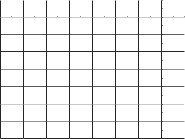

% summary(dtbl)

sessions=unique(dtbl.Var1);

ises=1;
% ises=5;

figure;
haxs=subplot(1,1,1);hold on;
haxss=tight_subplot(8,8,0,0,0);

cnt=0;
allgaps=zeros(1,18);
clear annotKp3ds
clear decodedKp3ds
for ises=1:10
    session=sessions{ises}
    flgses=strcmp(dtbl.Var1,session);
    currdtbl=dtbl(flgses,:);
    
        
    dirPickleRoot='data';
    picklefile=sprintf('%s/%s/kp3d_fxdJointLen.pickle',dirPickleRoot,session);
    if ~exist(picklefile)
        dirPickleRoot2='Z:\kaneko\monkey3d\pipeline\results\3d_v0p8_dark'
        picklefile2=sprintf('%s/%s/kp3d_fxdJointLen.pickle',dirPickleRoot2,session);
        mkdir(sprintf('%s/%s',dirPickleRoot,session));
        copyfile(picklefile2,picklefile)        
    end 

    fid=py.open(picklefile,'rb');
    data=py.pickle.load(fid);
    data=struct(data);
    kp3d=double(data.kp3d);

    for ifrm=1:height(currdtbl);
        cnt=cnt+1;
        ianim=1;

        currfrm=round(mean(cell2mat(table2cell(currdtbl(ifrm,2:end)))));
        currfrm=currfrm-24*5;

        currKp3d=squeeze(kp3d(ianim,currfrm,:,:));

        frmName=currdtbl(ifrm,:).Row;


        jsondata=readjson(sprintf('./labeledGT/valbin1_nanim1_nfrm100/%s.json',frmName{1}));
        annotKp3d=squeeze(jsondata.keypoints_3d(ianim,1:18,:));
% 
%         if 1            
%             haxs=haxss(cnt);
%             axes(haxs);
%             hold on;
%             [hplts, hplt_skpt] = plotMarmo3D(annotKp3d, haxs);
%             [hplts, hplt_skpt] = plotMarmo3D(currKp3d, haxs);
%             view([10 20]);
%         end

        allgaps(cnt,:)=(vecnorm((annotKp3d-currKp3d),2,2))';

        annotKp3ds(:,:,:,cnt)=annotKp3d;
        decodedKp3ds(:,:,:,cnt)=currKp3d;

    end
end

session = 'dailylife_cj357_20221009_090000'

dirPickleRoot2 = 'Z:\kaneko\monkey3d\pipeline\results\3d_v0p8_dark'

session = 'dailylife_cj357_20221009_140000'

dirPickleRoot2 = 'Z:\kaneko\monkey3d\pipeline\results\3d_v0p8_dark'

session = 'dailylife_cj357_20221010_110000'

dirPickleRoot2 = 'Z:\kaneko\monkey3d\pipeline\results\3d_v0p8_dark'

session = 'dailylife_cj357_20221010_160000'

dirPickleRoot2 = 'Z:\kaneko\monkey3d\pipeline\results\3d_v0p8_dark'

session = 'dailylife_cj425_20220514_130000'

dirPickleRoot2 = 'Z:\kaneko\monkey3d\pipeline\results\3d_v0p8_dark'

session = 'dailylife_cj425_20220611_150000'

dirPickleRoot2 = 'Z:\kaneko\monkey3d\pipeline\results\3d_v0p8_dark'

session = 'dailylife_cj425_20220806_090000'

dirPickleRoot2 = 'Z:\kaneko\monkey3d\pipeline\results\3d_v0p8_dark'

session = 'dailylife_cj425_20220903_110000'

dirPickleRoot2 = 'Z:\kaneko\monkey3d\pipeline\results\3d_v0p8_dark'

session = 'dailylife_cj425_20221015_130000'

dirPickleRoot2 = 'Z:\kaneko\monkey3d\pipeline\results\3d_v0p8_dark'

session = 'dailylife_cj425_20221106_100000'

dirPickleRoot2 = 'Z:\kaneko\monkey3d\pipeline\results\3d_v0p8_dark'

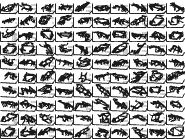

save('SingleAnimal.mat','annotKp3ds','decodedKp3ds');

for ianim=1:1
    hfig=figure;
    haxs=subplot(1,1,1);hold on;
    haxss=tight_subplot(10,10,0,0,0);        
    for ifrm=1:100    
        annotKp3d=squeeze(annotKp3ds(:,:,ianim,ifrm));
        currKp3d=squeeze(decodedKp3ds(:,:,ianim,ifrm));
        haxs=haxss(ifrm);
        axes(haxs);
        hold on;
        [hplts, hplt_skpt] = plotMarmo3D(annotKp3d, haxs);
        [hplts, hplt_skpt] = plotMarmo3D(currKp3d, haxs);
        view([10 20]);
    end
end